故障未知的实验, 电机最小转速是0

clear
clc
 
ulogOBJ = ulogreader("log_7_2022-4-12-11-06-24.ulg");
msg = readTopicMsgs(ulogOBJ);

## 确定known_logger的序号，提取log数据

更换log文件后需要修改下面的数值，找到msg中对应的known_logger的序号是多少。

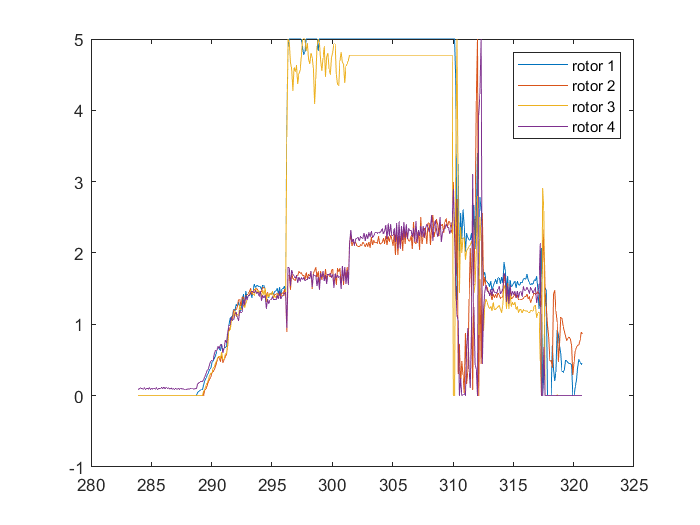

 
% 获取known_logger数据
logSampleRate = 10;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 读取数据
tDes = known_logger.tdes;

figure(11)
clf
plot(time,tDes(:,1))
hold on
plot(time,tDes(:,2))
hold on
plot(time,tDes(:,3))
hold on
plot(time,tDes(:,4))
legend('rotor 1','rotor 2','rotor 3','rotor 4')

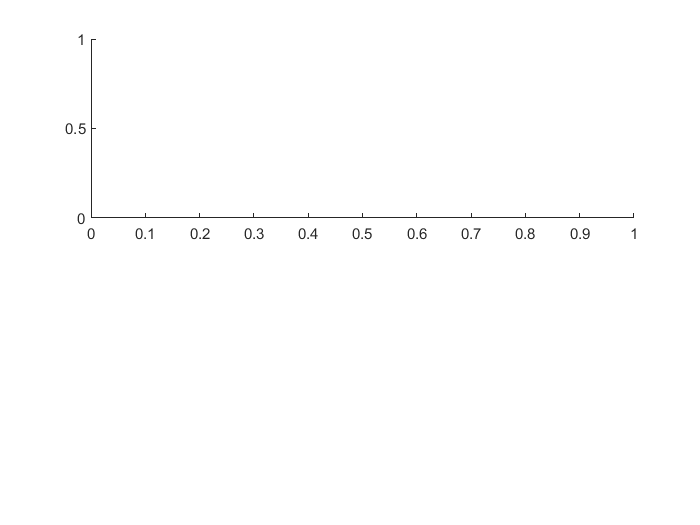

figure(12)
clf
subplot(2,1,1)

% plot(relativeTime,known_logger.h1)
% hold on
% plot(relativeTime,known_logger.h1d)
% subplot(2,1,2)
% plot(relativeTime,known_logger.h2)
% hold on
% plot(relativeTime,known_logger.h2d)

 
% 获取sensor_combined数据
logSampleRate = 400;
sensor_combined = msg.TopicMessages{24};
% 生成相对时间
log_time = sensor_combined.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
gyro = sensor_combined.gyro_rad;

无法识别表变量名称 'gyro_rad'。


% 画图
figure(13)
plot(relativeTime,gyro(:,3))